 % 预处理

eeglab: options file is C:\Users\crescent\eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
--------------------------------------------------------------------------------------------------------------------------------------------
%Equivalent command:
 erplab_running_version(   'tooltype', 'ERPLAB' 'version', '10.02' );
--------------------------------------------------------------------------------------------------------------------------------------------
Go back to ERPLAB menu

EEGLAB: adding "ERPLAB" v10.02 (see >> help eegplugin_erplab) - new version 10.1 available
EEGLAB: adding "ICLabel" v1.4 (see >> help eegplugin_iclabel) - new version 1.6 available
EEGLAB: adding "clean_rawdata" v2.91 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v5.3 (see >> help eegplugin_dipfit) - new version 5.4 available
EEGLAB: adding "firfilt" v2.7.1 (see >> help eegplugi

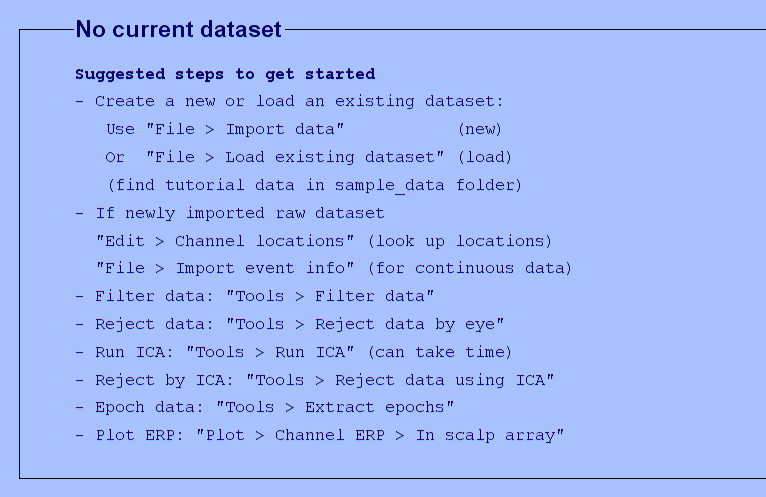

% 清理工作区，清理命令窗口
clear;
clc;

eeglab;

% 预处理步骤：
% 1. 导入CNT格式的数据：file - import - CNT
% 2. 对各个导联的头皮坐标进行定位：edit - channel locations - 选择坐标文件D:\eeglab\eeglab2023.1\plugins\dipfit\standard_BEM\elec\standard_1005.elc
% 3. 删除无用电极（一般是BC1、BC2、HEOG、VEOG）：edit - select data - channels - remove
% 4. 滤波（按顺序-高通0.1Hz，低通40Hz，陷波48~52Hz（点notch filter））：tools - filter the data - basic FIR filter
% 5. 降采样率（一般降到250~500就可以）:tools - change sampling rate
% 6. 切片与基线矫正（ERP必须）：tools - extra epochs - 选择mark - 设定分段时长（-1~2s） - 基线矫正（-1~0）
% 7. 插值坏导（如有）：plot - channel data，看是否有坏导 - tools - interpolate - 选择坏导
% 8. 去坏段（如有）：plot - channel data，看是否有坏段，选中，点击reject
% 9. 重参考（一般是双侧乳突M1/M2平均值或全头平均）：tools - re-reference data
% 10. 进行ICA（independent component analysis）：tools - decompose data by ICA
    % 【特别注意】ICA原理：鸡尾酒会，分离出来的成分数量一定小于或等于有效导联数量（分解的成分不可能大于合成的成分数）    
    % 【特别注意】所以，如果被试的数据经过插值坏导的操作，那么需要在'extended',1后加参数：'pca',m-n
    % 【特别注意】其中m为总导联数，n为坏导数。若没有插值，则默认
    % 【特别注意】跑完ICA不会自动保存数据，一定要手动保存
% 11.根据ICA的结果移除伪迹（inspect label/components by map）：
    % 【手动方法】tools - reject data using ICA - reject components by map - 根据提示与主观判断点击reject来标记删除成分 - tools - remove components from data
    % 【自动方法-推荐】tools - classify component using IClabel - flag components as artifact - 设定各个成分的阈值 - tools - remove components from data
    % 【提示】根据自身经验，可以先使用自动方法去一遍，然后再手动方法再去一遍
% 12.剔除伪迹数据段：
    %【自动阈限法】tools - reject data epochs - reject extreme values - 上下限设置为100毫伏 - 去除标记trials？ - YES
   % 【手动剔除】 inspect/reject data by eye - 框选两个选项 - 浏览所有epochs - reject

% set文件是CNT文件在进行一系列处理之后（切片，滤波等）在源文件CNT基础上生成的处理后数据
% fdt文件是CNT文件在EEGLAB中进行加工后，保存为set文件时创建的附属文件，可能用于储存各种在EEGLAB中运行保存下来的信息
% spl文件保存的是ICA的权重矩阵（weights matrix），通过加载这个文件，EEGLAB可以直接回复ICA的结果而不需要重新跑ICA